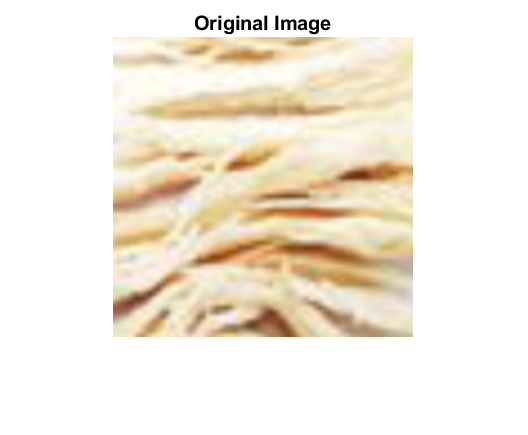

% Read the image
img = imread('Chicken.png');

% Display the original image
figure;
imshow(img);
title('Original Image');

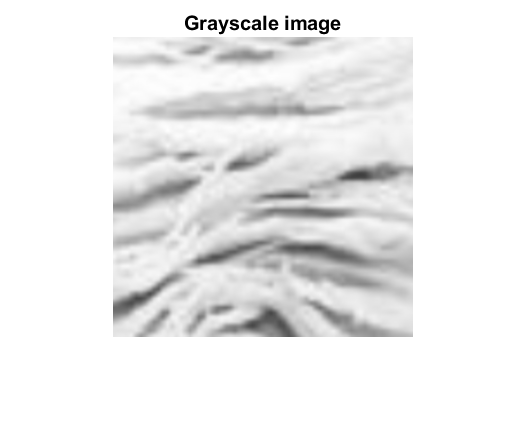


% Convert to grayscale
img_gray = rgb2gray(img);

% Show grayscale image
figure;
imshow(img_gray);
title('Grayscale image');

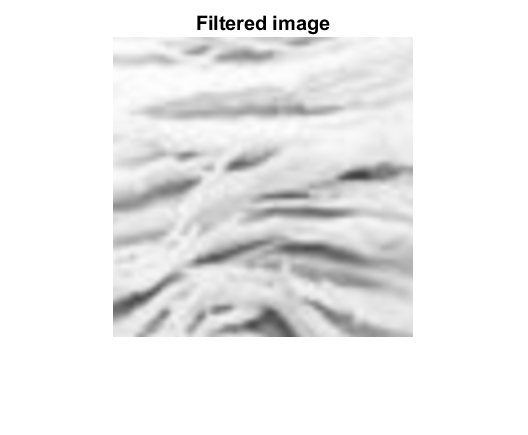


% Apply Gaussian filtering for noise reduction
img_filtered = imgaussfilt(img_gray, 1); % Adjust the standard deviation (sigma) as needed

% Show filtered image
figure;
imshow(img_filtered);
title('Filtered image');

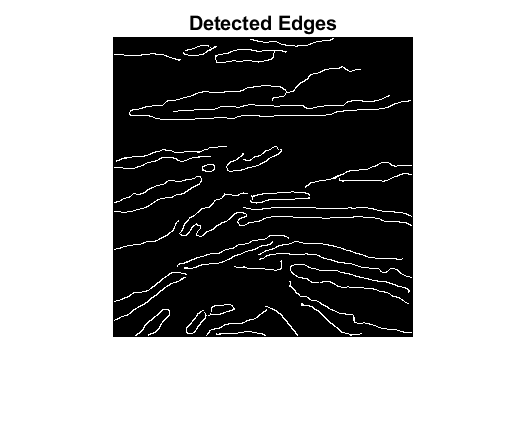


% Edge detection using Canny method with specified thresholds
low_threshold = 0.1; % Adjust as needed
high_threshold = 0.4; % Adjust as needed
edges = edge(img_filtered, 'Canny', [low_threshold, high_threshold]);

% Display the edges
figure;
imshow(edges);
title('Detected Edges');


% Extract edges properties
edges_props = regionprops(edges, 'PixelList');

% Calculate image dimensions in mm
image_width_mm = 20; % Width of the object in mm
image_height_mm = 20; % Height of the object in mm

% Pixel-to-mm conversion ratio
pixel_to_mm_ratio_width = size(img, 2) / image_width_mm;
pixel_to_mm_ratio_height = size(img, 1) / image_height_mm;

% Initialize arrays to store edge parameters
num_edges = numel(edges_props);
edge_angles = zeros(1, num_edges);
edge_distances = zeros(1, num_edges);
edge_lengths = zeros(1, num_edges);

% Calculate parameters for each edge
for i = 1:num_edges
    pixel_list = edges_props(i).PixelList;
    
    % Ensure at least 2 points to compute the path length
    if size(pixel_list, 1) < 2
        continue;
    end
    
    try
        % Compute edge direction using the slope of the line
        direction_vector = pixel_list(end, :) - pixel_list(1, :);
        edge_angles(i) = atan2d(direction_vector(2), direction_vector(1)); % Angle in degrees
        
        % Calculate distance between edges (horizontal center-to-center)
        center_x = size(img, 2) / 2; % Horizontal center of the image
        distances = abs(pixel_list(:, 1) - center_x);
        edge_distances(i) = mean(distances) / pixel_to_mm_ratio_width; % Mean distance in mm
        
        % Calculate maximum path length of each edge in mm
        edge_lengths(i) = max(pdist(pixel_list)) / sqrt(pixel_to_mm_ratio_width^2 + pixel_to_mm_ratio_height^2); % Maximum path length in mm
    catch
        continue;
    end
end

% Display the extracted parameters
disp(['Number of Edges: ', num2str(num_edges)]);

Number of Edges: 37


disp(['Edge Angles (degrees): ', num2str(edge_angles)]);

Edge Angles (degrees): 4.33231     -6.53663     -13.5704     -23.6294      -20.556     -31.2005     -7.25319     -2.44531     -30.4655     -4.23639     -13.6713     -1.97493     -10.3048     -15.8594     -9.86581     -30.9638      14.0362     -22.6199     -12.9946     -3.22452      2.33731     -15.2551      2.43665     -15.9454      3.06649    -0.690277     -1.94149            0      1.59114      6.75357      42.1844      22.6865      11.8644      26.5651     -11.2059      13.4218     -3.17983


disp(['Distances between Edges (mm): ', num2str(edge_distances)]);

Distances between Edges (mm): 7.5644      6.6305      6.8498      7.4429      7.4414      7.4444      6.2283      4.2677      7.1566      3.7732      2.5349      3.8302      4.0638      2.3485      4.3615      4.4182      3.6036       1.745      2.7208      1.3612      1.4788      1.2304     0.91222     0.58788      4.5665      2.1187      1.3274      1.3267      4.4771      4.8902        1.42      5.4219      5.3196      4.4277      6.2297       6.798      7.5154


disp(['Maximum Path Lengths of Edges (mm): ', num2str(edge_lengths)]);

Maximum Path Lengths of Edges (mm): 3.12019      4.55509      4.38634      3.31227      3.62491      3.91294      5.23344      13.2629      1.98942      10.2102      5.40822      10.9431      1.59025      4.33923      1.10955      1.32077     0.612826      3.08257       1.2693      3.36815      2.31181       2.7313      2.23358      1.71594      7.93095      3.91294      2.78767      2.73577      6.79084      7.21542      2.03579      6.23342      5.73217      3.16228      5.10338      4.26484      3.40588
